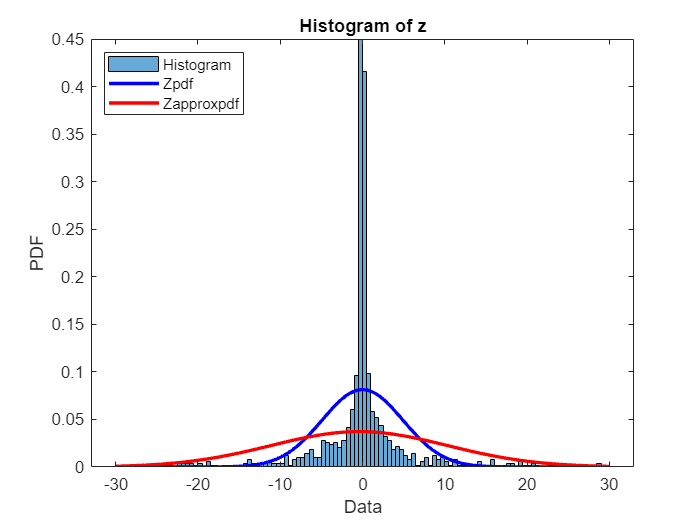

clear
clc
%parta

%forx
mu=0;
sigma=2;

% Generate a large number of samples from x
n=10e2;
x = normrnd(0, 2, 1, n);

% Calculate the corresponding values of z
% z = x.^3;
% z = @(x) 3*x;
z= @(x) x.^3;
[mu_z, Sigma_z, y_z] = approxGaussianTransform(mu, sigma, z, n);

% Compute the histogram of z
bins = -30:0.5:30; % Define the bins for the histogram
hist_z = histogram(y_z, bins, 'Normalization', 'pdf');

% Plot the theoretical PDF of z
% z_pdf = normpdf(bins, 0, sqrt(18)); % Theoretical PDF of z
z_pdf = normpdf(bins, 0, sqrt(24)); 
z_approx_pdf = normpdf(bins, mu_z, sqrt(Sigma_z));
hold on % Add the histogram to the same plot
plot(bins, z_pdf, 'b-', 'LineWidth', 2)
plot(bins, z_approx_pdf, 'r-', 'LineWidth', 2)
% Add legend and axis labels
legend('z', 'Location', 'NorthWest')
xlabel('Data')
ylabel('PDF')
legend('Histogram','Zpdf','Zapproxpdf')
title('Histogram of z')